## Φόρτωση εικόνας


% Εκαθάριση 
close all; clear; clc;

% Παράμετροι χρήστη
imgFile        = fullfile('Images','Ασκηση 5','new_york.png');   % εικόνα εισόδου
desiredSNR_dB  = 10;                     % επιθυμητό SNR μετά τη θόλωση
thrList        = [0, logspace(-4,-1,15)];% υποψήφια κατώφλια (πλέον περιλαμβάνει T=0)
doSave         = true;                   % σημαία: αποθήκευση σχημάτων & εικόνων
errZoomFactor  = 5;                      % πολλαπλασιαστής μεγέθυνσης χάρτη σφάλματος
rng(7);                                  % αναπαραγωγιμότητα θορύβου

% Βοηθητικές
mseFun  = @(X,Y) mean((X(:)-Y(:)).^2);
psnrFun = @(X,Y) 10*log10(1/mseFun(X,Y));
ssimFun = @(X,Y) ssim(X,Y);

fprintf('> Φόρτωση εικόνας: %s\n', imgFile);

> Φόρτωση εικόνας: Images\Ασκηση 5\new_york.png


I = im2double(imread(imgFile));
if size(I,3) == 3
    I = rgb2gray(I);                        % επεξεργασία σε γκρι
end
[H, W] = size(I);


## Διακύμανση θορύβου για SNR

sigVar   = var(I(:));
noiseVar = sigVar / 10.^(desiredSNR_dB/10);

% Εύρεση περιοχής λεπτομέρειας 
zoomRect = pickDetailPatch(I, 0.15);       % βοηθητική συνάρτηση


## Εκτίμηση PSF


fprintf('> Εκτίμηση PSF μέσω psf.p ...\n');

> Εκτίμηση PSF μέσω psf.p ...


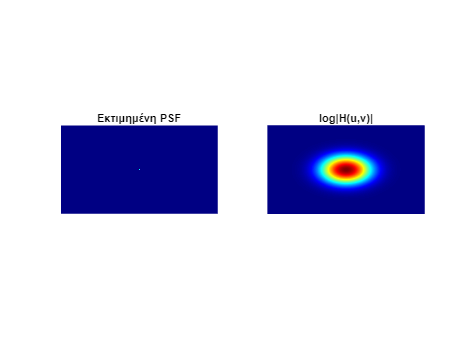

addpath(fileparts(imgFile));                % δείχνει που βρίσκεται το psf.p
impulse          = zeros(H,W);
impulse(ceil(H/2), ceil(W/2)) = 1;         % δ[n,n]
kernel           = psf(impulse);
kernel           = kernel / sum(kernel(:));% κανονικοποίηση ενέργειας

% Φάσμα συχνότητας 
K     = fftshift(fft2(kernel));
figure('Name','PSF και το φάσμα της');
subplot(1,2,1), imagesc(kernel), axis image off, colormap hot
title('Εκτιμημένη PSF');
subplot(1,2,2), imagesc(log1p(abs(K))), axis image off, colormap jet
title('log|H(u,v)|');


% Θόλωση και προσθήκη θορύβου
fprintf('> Θόλωση και προσθήκη θορύβου ...\n');

> Θόλωση και προσθήκη θορύβου ...


blurOnly    = psf(I);                                 % μέσω δοσμένου φίλτρου
blurNoisy   = blurOnly + sqrt(noiseVar)*randn(size(I));
blurNoisy   = min(max(blurNoisy,0),1);                % περιορισμός

stats = @(X) sprintf('MSE %.4g | PSNR %.2f dB | SSIM %.4f' , ...
                     mseFun(I,X), psnrFun(I,X), ssimFun(I,X));

fprintf('   Θόλωση μόνο :      %s\n', stats(blurOnly));

   Θόλωση μόνο :      MSE 6.484 | PSNR -8.12 dB | SSIM 0.1815


fprintf('   Θόλωση+Θορυβος: %s\n', stats(blurNoisy));

   Θόλωση+Θορυβος: MSE 0.2701 | PSNR 5.68 dB | SSIM 0.2871


## Φάσματα θολωμένης-θορυβώδους εικόνας & PSF

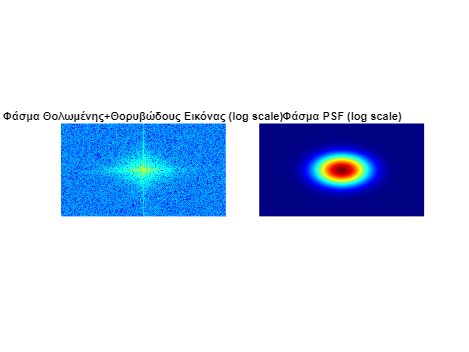


F_blurSpect = fftshift(fft2(blurNoisy));
figure('Name','Επίδραση θόλωσης και θορύβου');
tiledlayout(1,2,'TileSpacing','compact');
nexttile
imagesc(log1p(abs(F_blurSpect))), axis image off, colormap jet
title('Φάσμα Θολωμένης+Θορυβώδους Εικόνας (log scale)');
nexttile
imagesc(log1p(abs(K))), axis image off, colormap jet
title('Φάσμα PSF (log scale)');
if doSave, saveas(gcf,'φασμα_θολωσης_θορυβου.png'); end

## Αντίστροφη με threshold


fprintf('\n> Εκτέλεση αντίστροφου φίλτρου για %d κατώφλια ...\n', numel(thrList));


> Εκτέλεση αντίστροφου φίλτρου για 16 κατώφλια ...



F_blur   = fft2(blurNoisy);
Hfreq    = fft2(kernel, H, W);

mseArr  = zeros(size(thrList));
psnrArr = zeros(size(thrList));
ssimArr = zeros(size(thrList));
restIm  = cell(numel(thrList),1);

for ii = 1:numel(thrList)
    T = thrList(ii);
    
    invH           = 1 ./ Hfreq;
    invH(abs(Hfreq) < T) = 0;     % εφαρμογή threshold
    
    F_hat          = F_blur .* invH;
    est            = real(ifft2(F_hat));
    est            = min(max(est,0),1);
    
    mseArr(ii)     = mseFun(I,est);
    psnrArr(ii)    = psnrFun(I,est);
    ssimArr(ii)    = ssimFun(I,est);
    restIm{ii}     = est;
    
    fprintf('   T=%.1e  -->  %s\n', T, stats(est));
end

   T=0.0e+00  -->  MSE 0.3303 | PSNR 4.81 dB | SSIM 0.0032
   T=1.0e-04  -->  MSE 0.3281 | PSNR 4.84 dB | SSIM 0.0031
   T=1.6e-04  -->  MSE 0.3269 | PSNR 4.86 dB | SSIM 0.0030
   T=2.7e-04  -->  MSE 0.3248 | PSNR 4.88 dB | SSIM 0.0030
   T=4.4e-04  -->  MSE 0.3213 | PSNR 4.93 dB | SSIM 0.0031
   T=7.2e-04  -->  MSE 0.316 | PSNR 5.00 dB | SSIM 0.0032
   T=1.2e-03  -->  MSE 0.3083 | PSNR 5.11 dB | SSIM 0.0040
   T=1.9e-03  -->  MSE 0.2999 | PSNR 5.23 dB | SSIM 0.0047
   T=3.2e-03  -->  MSE 0.2926 | PSNR 5.34 dB | SSIM 0.0071
   T=5.2e-03  -->  MSE 0.2901 | PSNR 5.37 dB | SSIM 0.0141
   T=8.5e-03  -->  MSE 0.2924 | PSNR 5.34 dB | SSIM 0.0271
   T=1.4e-02  -->  MSE 0.2975 | PSNR 5.27 dB | SSIM 0.0479
   T=2.3e-02  -->  MSE 0.304 | PSNR 5.17 dB | SSIM 0.0753
   T=3.7e-02  -->  MSE 0.3099 | PSNR 5.09 dB | SSIM 0.1076
   T=6.1e-02  -->  MSE 0.3143 | PSNR 5.03 dB | SSIM 0.1374
   T=1.0e-01  -->  MSE 0.3177 | PSNR 4.98 dB | SSIM 0.1608


## Επιλογή “καλύτερου” threshold


[~,bestMSE]  = min(mseArr);
[~,bestPSNR] = max(psnrArr);
[~,bestSSIM] = max(ssimArr);

fprintf('\n>> Καλύτερα thresholds:\n');


>> Καλύτερα thresholds:


fprintf('   κατά MSE :  T=%.2e\n', thrList(bestMSE));

   κατά MSE :  T=5.18e-03


fprintf('   κατά PSNR:  T=%.2e\n', thrList(bestPSNR));

   κατά PSNR:  T=5.18e-03


fprintf('   κατά SSIM:  T=%.2e\n', thrList(bestSSIM));

   κατά SSIM:  T=1.00e-01


## Καμπύλες MSE / PSNR / SSIM

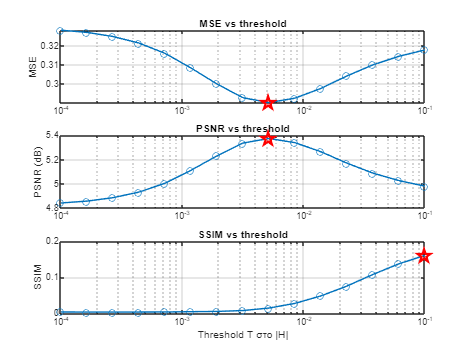


figure('Name','Καμπύλες απόδοσης');
subplot(3,1,1), semilogx(thrList, mseArr, '-o'), grid on
ylabel('MSE'), title('MSE vs threshold')
hold on, plot(thrList(bestMSE), mseArr(bestMSE),'rp','MarkerSize',12,'LineWidth',2), hold off

subplot(3,1,2), semilogx(thrList, psnrArr, '-o'), grid on
ylabel('PSNR (dB)'), title('PSNR vs threshold')
hold on, plot(thrList(bestPSNR), psnrArr(bestPSNR),'rp','MarkerSize',12,'LineWidth',2), hold off

subplot(3,1,3), semilogx(thrList, ssimArr, '-o'), grid on
xlabel('Threshold T στο |H|'), ylabel('SSIM'), title('SSIM vs threshold')
hold on, plot(thrList(bestSSIM), ssimArr(bestSSIM),'rp','MarkerSize',12,'LineWidth',2), hold off

if doSave, saveas(gcf,'καμπυλη_threshold.png'); end

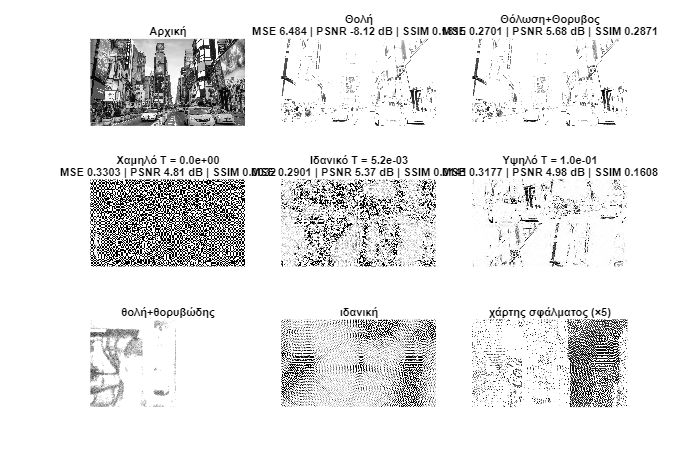

> Αποθήκευση εικόνων ...



% Οπτικά αποτελέσματα 
idxLo     = 1;
idxOpt    = bestPSNR;
idxHi     = numel(thrList);

figure('Name','Οπτική σύγκριση','Position',[50 50 1200 800]);
tiledlayout(3,3,'TileSpacing','compact');

nexttile,  imshow(I),               title('Αρχική');
nexttile,  imshow(blurOnly),        title({'Θολή';stats(blurOnly)});
nexttile,  imshow(blurNoisy),       title({'Θόλωση+Θορυβος';stats(blurNoisy)});

nexttile,  imshow(restIm{idxLo}),   title({sprintf('Χαμηλό T = %.1e',thrList(idxLo));stats(restIm{idxLo})});
nexttile,  imshow(restIm{idxOpt}),  title({sprintf('Ιδανικό T = %.1e',thrList(idxOpt));stats(restIm{idxOpt})});
nexttile,  imshow(restIm{idxHi}),   title({sprintf('Υψηλό T = %.1e',thrList(idxHi));stats(restIm{idxHi})});

rows = zoomRect(1):zoomRect(2); cols = zoomRect(3):zoomRect(4);

nexttile, imshow(blurNoisy(rows,cols)), title('θολή+θορυβώδης');
nexttile, imshow(restIm{idxOpt}(rows,cols)), title('ιδανική');
nexttile, imshow(errZoomFactor*abs(I(rows,cols)-restIm{idxOpt}(rows,cols))), ...
                 title('χάρτης σφάλματος (×5)');

if doSave
    fprintf('> Αποθήκευση εικόνων ...\n');
    saveas(gcf,'αποτελεσμα_αντ_φιλτρου.png');
    imwrite(restIm{idxOpt}, 'αποκατασταθηκε_ιδανικο.png');
    imwrite(restIm{idxLo} , 'αποκατασταθηκε_χαμηλο.png');
    imwrite(restIm{idxHi} , 'αποκατασταθηκε_υψηλο.png');
end



% Συναρτήσεις
function rect = pickDetailPatch(img, percent)
    [h,w]   = size(img);
    ph      = round(h*percent);
    pw      = round(w*percent);
    r1      = round(h/2 - ph/2);
    c1      = round(w/2 - pw/2);
    r1      = max(1,r1);               c1  = max(1,c1);
    r2      = min(h,r1+ph-1);          c2  = min(w,c1+pw-1);
    rect    = [r1 r2 c1 c2];
end
